**Data**

x = [3 4 5 7 8 9 11 12]';

y = [6.9 10.0 11.1 15.0 15.7 16.2 24.0 27.5]';


**Plot data**

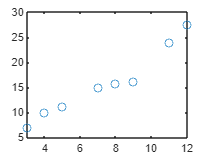


plot(x,y,'o')

**Create Z matrix**


z = [ones(8,1) x]

z =      1     3
     1     4
     1     5
     1     7
     1     8
     1     9
     1    11
     1    12


**Solve for unknown parameters  a  **

a = (z'*z) \ (z'*y)

a =     0.3861
    2.0900


**Plot data and the best fitted curve**

xx = 3 : 0.5 : 12

xx =     3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000



yy = a(1) + a(2)*xx

yy =     6.6562    7.7012    8.7462    9.7912   10.8362   11.8812   12.9262   13.9712   15.0162   16.0613   17.1063   18.1513   19.1963   20.2413   21.2863   22.3313   23.3763   24.4213   25.4663


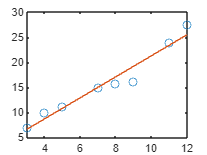


plot(x,y,'o',xx,yy,'-')

**Compute  Sr  (the sum of the squares of the residuals between the best-fit curve and the data)**

Sr = sum((y-z*a).^2)

Sr = 17.1814

**Compute  St   (the sum of the squares of the residuals between the data points and the mean)**

St = sum((y-mean(y)).^2)

St = 339.8800

**Compute  r2  (the coefficient of determination)**

r2 = 1 - Sr/St

r2 = 0.9494

**Compute  syx  (the standard error of the estimate)  **


syx = sqrt(Sr/(length(x)-length(a)))

syx = 1.6922

**Predict the value of y for the given x**

xtest = 6;
predict_y = a(1) + a(2)*xtest

predict_y = 12.9262